%dx,dy: calculated displacement field for rotating counterclockwise by theta
%I0: Result of rotation of I1 by theta with dx, dy using bilinear interpolation
%I1prime: Result of rotation of I0 back to I1 using interpolated inverse rotation displacement field, again, using bilinear interpolation 


input1=im2double(rgb2gray(imread("ninebynine.png")))

input1 =     0.7843    0.7843    0.7843    0.7843    0.7882    0.7961    0.7843    0.7843    0.7843
    0.7843    0.8078    0.8196    0.7843    0.7843    0.8471    0.9725    0.9725    0.8627
    0.8588    0.9059    0.8549    0.7843    0.7843    0.9725    1.0000    1.0000    0.9922
    0.8863    1.0000    0.9255    0.8863    0.7843    0.8863    1.0000    1.0000    0.9137
    0.7843    0.8863    1.0000    1.0000    0.7843    0.7843    0.7843    0.7843    0.7843
    0.8980    0.7843    0.7843    0.7843    0.8431    0.7843    0.7529    0.7843    0.9059
    0.7843    0.7529    0.7529    0.7529    0.7529    0.7529    0.7529    0.7529    0.7608
    0.7529    0.7529    0.7529    0.7529    0.6784    0.5176    0.4824    0.5176    0.6549
    0.7529    0.7529    0.6784    0.5176    0.4824    0.4824    0.4824    0.4824    0.4941


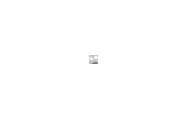

imshow(input1)


interpolated=catmull(input1,16)

interpolated =     0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7843    0.7846
    0.7843    0.7844    0.7845    0.7846    0.7847    0.7848    0.7849    0.7850    0.7850    0.7851    0.7852    0.7853    0.7854    0.7855    0.7856    0.7857    0.7858    0.7858    0.7859    0.7859    0.7860    0.7860    0.7861    0.7861    0.7862    0.7862    0.7862    0.7863    0.7863    0.7864    0.7864    0.7865    0.7865    0.7864    0.7862    0.7861    0.7860    0.7858    0.7857    0.7856    0.7854    0.7853    0.7851    0.7850    0.7849    0.7847    0.7846    0.7845    

result=bilinear(input1,1.2,1.2)

result = 0.7853


theta=pi/12;

I1 = interpolated;
[I0,dx,dy,I1prime]=rotations(I1,theta)

I0 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

dx =    18.7452   18.7111   18.6770   18.6429   18.6089   18.5748   18.5407   18.5066   18.4726   18.4385   18.4044   18.3704   18.3363   18.3022   18.2681   18.2341   18.2000   18.1659   18.1318   18.0978   18.0637   18.0296   17.9955   17.9615   17.9274   17.8933   17.8592   17.8252   17.7911   17.7570   17.7229   17.6889   17.6548   17.6207   17.5866   17.5526   17.5185   17.4844   17.4503   17.4163   17.3822   17.3481   17.3141   17.2800   17.2459   17.2118   17.1778   17.1437   17.1096   17.0755
   18.4863   18.4523   18.4182   18.3841   18.3501   18.3160   18.2819   18.2478   18.2138   18.1797   18.1456   18.1115   18.0775   18.0434   18.0093   17.9752   17.9412   17.9071   17.8730   17.8389   17.8049   17.7708   17.7367   17.7026   17.6686   17.6345   17.6004   17.5663   17.5323   17.4982   17.4641   17.4300   17.3960   17.3619   17.3278   17.2938   17.2597   17.2256   17.1915   17.1575   17.1234   17.0893   17.0552   17.0212   16.9871   16.9530   16.9189   16.8849   16.8508   1

dy =   -14.3837  -14.1249  -13.8660  -13.6072  -13.3484  -13.0896  -12.8308  -12.5719  -12.3131  -12.0543  -11.7955  -11.5367  -11.2778  -11.0190  -10.7602  -10.5014  -10.2426   -9.9837   -9.7249   -9.4661   -9.2073   -8.9485   -8.6897   -8.4308   -8.1720   -7.9132   -7.6544   -7.3956   -7.1367   -6.8779   -6.6191   -6.3603   -6.1015   -5.8426   -5.5838   -5.3250   -5.0662   -4.8074   -4.5485   -4.2897   -4.0309   -3.7721   -3.5133   -3.2545   -2.9956   -2.7368   -2.4780   -2.2192   -1.9604   -1.7015
  -14.4177  -14.1589  -13.9001  -13.6413  -13.3825  -13.1237  -12.8648  -12.6060  -12.3472  -12.0884  -11.8296  -11.5707  -11.3119  -11.0531  -10.7943  -10.5355  -10.2766  -10.0178   -9.7590   -9.5002   -9.2414   -8.9825   -8.7237   -8.4649   -8.2061   -7.9473   -7.6885   -7.4296   -7.1708   -6.9120   -6.6532   -6.3944   -6.1355   -5.8767   -5.6179   -5.3591   -5.1003   -4.8414   -4.5826   -4.3238   -4.0650   -3.8062   -3.5473   -3.2885   -3.0297   -2.7709   -2.5121   -2.2533   -1.9944   -

I1prime =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

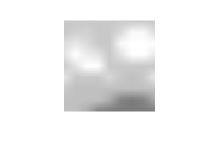

imshow(I1)

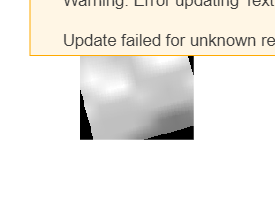

imshow(I0)

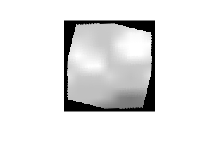

imshow(I1prime)

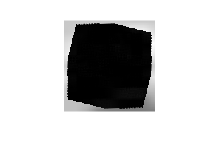

imshow(abs(I1 - I1prime))

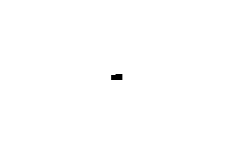


ctrl_disp = zeros([9 9 2]);
for j = 0:8
    for i = 0:8
        ctrl_disp(j+1, i+1, 1) = dx(j*16+1, i*16+1);
        ctrl_disp(j+1, i+1, 2) = dy(j*16+1, i*16+1);
    end
end
%#1. 9x9 -> 129x129 disp vectors
imshow(ctrl_disp(:,:,1))

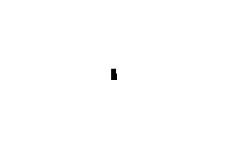

imshow(ctrl_disp(:,:,2))

extended_ctrl_disp = control_displacement_vectors(ctrl_disp)

extended_ctrl_disp = extended_ctrl_disp(:,:,1) =

   18.7452   18.7111   18.6770   18.6429   18.6089   18.5748   18.5407   18.5066   18.4726   18.4385   18.4044   18.3704   18.3363   18.3022   18.2681   18.2341   18.2000   18.1659   18.1318   18.0978   18.0637   18.0296   17.9955   17.9615   17.9274   17.8933   17.8592   17.8252   17.7911   17.7570   17.7229   17.6889   17.6548   17.6207   17.5866   17.5526   17.5185   17.4844   17.4503   17.4163   17.3822   17.3481   17.3141   17.2800   17.2459   17.2118   17.1778   17.1437   17.1096   17.0755   17.0415   17.0074   16.9733   16.9392   16.9052   16.8711   16.8370   16.8029   16.7689   16.7348   16.7007   16.6666   16.6326   16.5985   16.5644   16.5303   16.4963   16.4622   16.4281   16.3940   16.3600   16.3259   16.2918   16.2578   16.2237   16.1896   16.1555   16.1215   16.0874   16.0533   16.0192   15.9852   15.9511   15.9170   15.8829   15.8489   15.8148   15.7807   15.7466   15.7126   15.6785   15.6444   15.6103   15.5763   15.5422

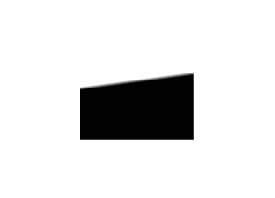

imshow(extended_ctrl_disp(:,:,1))

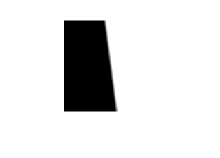

imshow(extended_ctrl_disp(:,:,2))

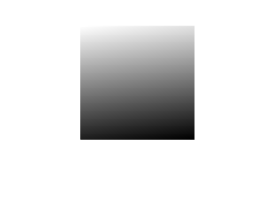


ect1_range = extended_ctrl_disp(:,:,1) - min(extended_ctrl_disp(:,:,1), [], 'all');
ect1_range = ect1_range / max(ect1_range(:), [], 'all');
ect2_range = extended_ctrl_disp(:,:,2) - min(extended_ctrl_disp(:,:,2), [], 'all');
ect2_range = ect2_range / max(ect2_range(:), [], 'all');
imshow(ect1_range)

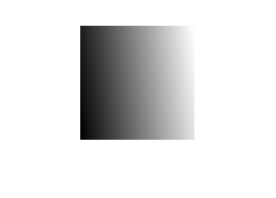

imshow(ect2_range)


extended_ctrl_disp(:,:,1) -dx 

ans = 	1.0e+-14 *

         0   -0.3553         0         0   -0.3553         0         0   -0.3553         0         0   -0.3553         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.3553         0         0   -0.3553   -0.3553         0   -0.3553   -0.3553         0   -0.3553   -0.3553         0         0   -0.3553         0         0   -0.3553         0         0   -0.3553         0         0         0         0         0         0         0         0   -0.3553         0         0   -0.3553         0         0   -0.3553         0         0   -0.3553         0         0   -0.3553         0         0   -0.3553         0         0         0

extended_ctrl_disp(:,:,2) -dy 


function [I0,dx,dy,I1prime]=rotations(I1,theta)
    
    centerpoint = floor(size(I1,1)/2) + 1;

    I0 = zeros(size(I1));
    dx = zeros(size(I1));
    dy = zeros(size(I1));
    for x = 1:size(I1,2)
        for y = 1:size(I1,1)
            vy = y - centerpoint;
            vx = x - centerpoint;
            rotmat = [vx*(cos(theta) - 1) - vy*sin(theta); vx*sin(theta) + vy*(cos(theta) - 1)];
            rx = rotmat(1,1);
            ry = rotmat(2,1);
            dx(y, x) = rx;
            dy(y, x) = ry;
            
            I0(y,x) = bilinear(I1, ry+y, rx+x);
        end
    end

    I1prime = zeros(size(I1));
    for j = 1:size(dx, 2)
        for i = 1:size(dx, 1)
            I1prime(j, i) = bilinear(I0, j-dy(j, i), i-dx(j, i));
        end
    end

end

function value = bilinear(I, y, x)
    x_ceil = ceil(x);
    y_ceil = ceil(y);
    x_floor = floor(x);
    y_floor = floor(y);
    tx = x-x_floor;
    ty = y-y_floor;

    if x > size(I, 2) | y > size(I, 1) | x < 1 | y < 1
        value = 0;
    else
        value = tx*(ty*I(y_ceil, x_ceil) + (1-ty)*I(y_ceil, x_floor)) + (1-tx)*(ty*I(y_floor, x_ceil) + (1-ty)*I(y_floor, x_floor));
    end
    
    
end

function value = interpolate_pixel(im, y, x)
    if rem(y, 1) == 0 & rem(x, 1) == 0
        value = im(y, x);
    else
        value = (im(floor(y), floor(x)) + im(ceil(y), ceil(x)) + im(floor(y), ceil(x)) + im(ceil(y), floor(x)))/4;
    end
end
    
function interpolated=catmull_helper(input1,control_point_spacing)
    control_points_y = [1:(size(input1, 1)-1)/control_point_spacing:size(input1, 1)];
    control_points_x = [1:(size(input1, 2)-1)/control_point_spacing:size(input1, 2)];

    interpolated = zeros([size(control_points_y, 2) size(control_points_x, 2)]);
    for y = 1:size(control_points_y, 2)
        for x = 1:size(control_points_x, 2)
            interpolated(y, x) = interpolate_pixel(input1, control_points_y(y), control_points_x(x));
        end
    end
end

function interpolated=catmull(input1,control_point_spacing)
    interpolated = catmull_helper(input1, control_point_spacing);
    while size(interpolated, 1) < 129
        control_point_spacing = control_point_spacing*2;
        interpolated = catmull_helper(interpolated, control_point_spacing);
    end
end

%input1 = 9x9x2 matrix
function extended = control_displacement_vectors(input1)
    extended = zeros([129 129 2]);
    extended(:,:,1) = catmull(input1(:,:,1), 16);
    extended(:,:,2) = catmull(input1(:,:,2), 16);
end